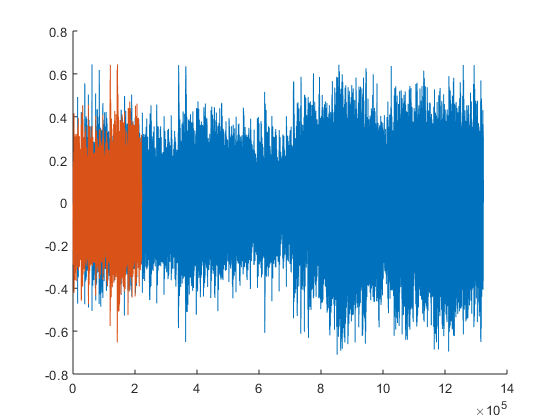

[S,Fs] = audioread('Music library\5 second a new beginning.mp3');
[T1,Fs1] = audioread('Music library\Cut down 30s\creative minds cut.mp3');
[T2,Fs2] = audioread('Music library\Cut down 30s\a new beginning cut.mp3');

S = mean(S,2);
T1 = mean(T1,2);
T2 = mean(T2,2);


timeInSeconds = numel(S)/Fs;
timeInSeconds1 = numel(T1)/Fs1;
timeInSeconds2 = numel(T2)/Fs2;



% plot(S(:,1))
% plot(T1(:,1))
% plot(T2(:,1))
% [P1,Q1] = rat(Fs/Fs1);          % Rational fraction approximation
% [P2,Q2] = rat(Fs/Fs2);          % Rational fraction approximation
% T1 = resample(T1,P1,Q1);        % Change sampling rate by rational factor
% T2 = resample(T2,P2,Q2);        % Change sampling rate by rational factor


[C1,lag1] = xcorr(T1,S);        
[C2,lag2] = xcorr(T2,S);       
% 
% figure
% ax(1) = subplot(2,1,1); 
% plot(lag1/Fs,C1,'k')
% ylabel('Amplitude')
% grid on
% title('Cross-correlation between Template 1 and Signal')
% 
% ax(2) = subplot(2,1,2); 
% plot(lag2/Fs,C2,'r')
% ylabel('Amplitude') 
% grid on
% title('Cross-correlation between Template 2 and Signal')
% xlabel('Time(secs)') 
% 
% 
% axis(ax(1:2),[-5 (timeInSeconds1) (min(C2)) (max(C2)) ])
% 
% [~,I] = max(abs(C2));
% SampleDiff = lag2(I)
% 
% timeDiff = SampleDiff/Fs
% 
delay = finddelay(S,C2);
% 
% alignedSignals = alignsignals(S,C2);
% % plot(alignedSignals)

hold on
plot(T2)
plot(S)